clear all 
close all
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


The system is 

G = 1/(s*(s+1)*(0.5*s+1));

Spec 1: Kv = 5;

Spec 2: Phi_m > 40 deg

Spec 3: gm > 10dB

# Lag compensator

For a lag controller we have

C = Kc (T*s+1)/(beta*T*s+1)

We need to design Kc, beta, and T

### Spec 1: Kv = 20

We compute Kv as

Kv = lim_{s \to 0} s L(s) = Kc

Then, we choose

Kc = 5;

The bode plot with this gain is given by

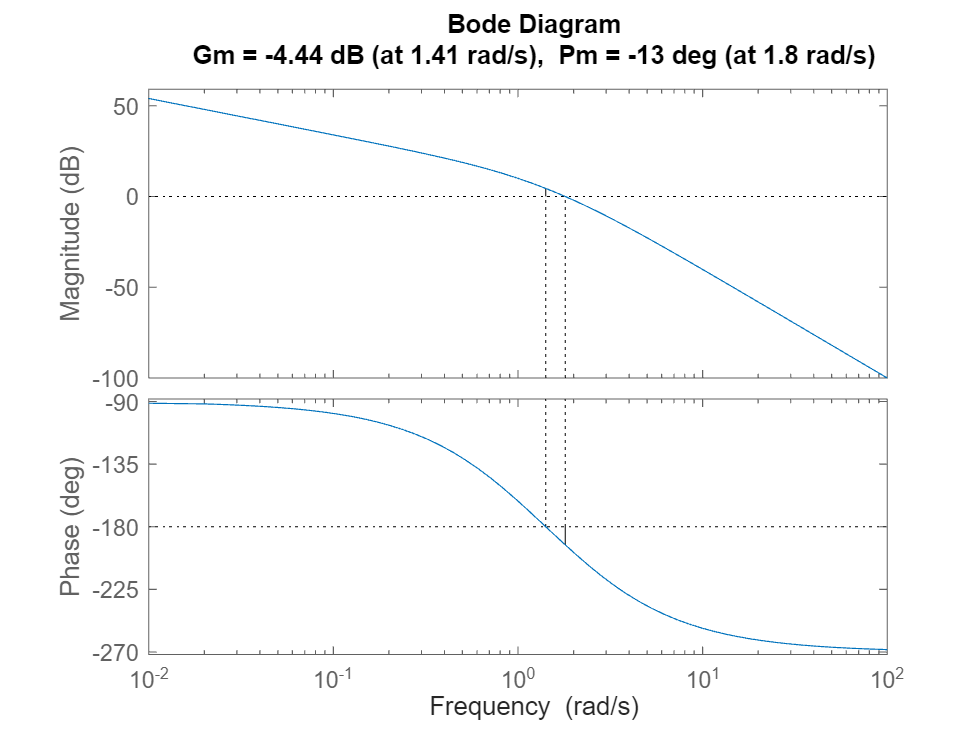

margin(Kc*G)

### Spec 2: phi_m > 40

The goal is to achieve a phase margin of at least 40 degrees (targeting around 50). The desired gain crossover frequency is near 0.5 rad/s, where the magnitude is roughly 19 dB. We want to reduce the gain at this frequency to achieve the desired phase margin. To calculate beta, we use the relation:

20 log (beta) = 19 dB

which gives

beta = 10^(19/20);

Finally, to choose T, we place the zero of the lag compensator one decade below the new gain crossover frequency to ensure minimal impact on phase margin:

T = 10/0.5;

This gives the lag compensator

C = Kc * (T*s+1)/(beta*T*s+1);

with bode plot

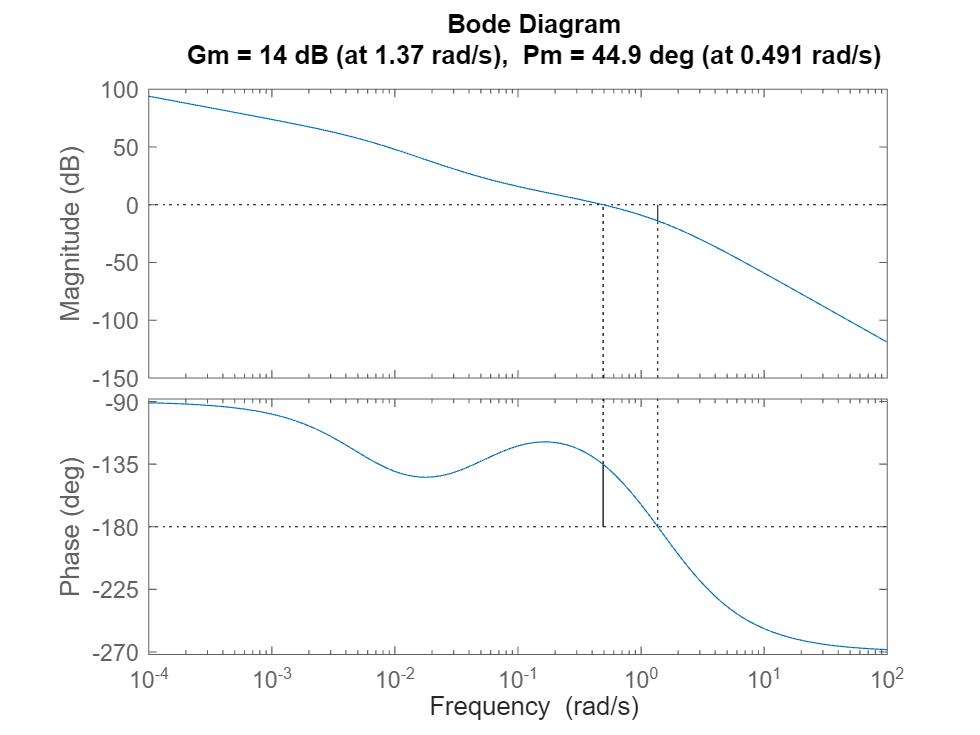

margin(C*G)

This design meets all specifications.